#### 1 - Sinal de referência para a tensão de saída do conversor Buck

clc;
clear;

A = 6;
offset = 6;
freq = 1 / 20e-3 % F = 50Hz / T = 20ms

freq = 50

freq_amostragem = 5000; % Fs = 5000Hz / Ts = 0.2ms

T = 1/freq;
Ts = 1/freq_amostragem;

rad_s = 2 * pi;

N = 100

N = 100

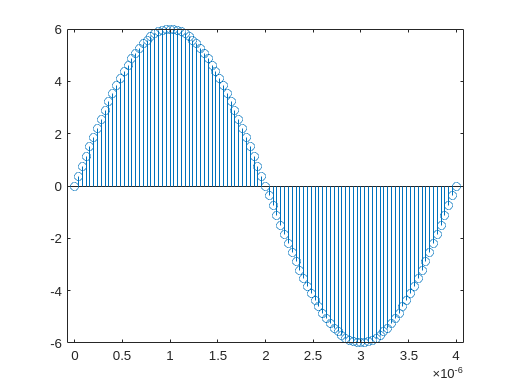

y = zeros(1, N);
x = zeros(1, N);

i = 1;
for n = 0:Ts:Ts*N
    x(i) = Ts * n;
    y(i) = A * sin(rad_s * freq * n);
    i = i + 1;
end

stem(x, y)

#### 3.3 - Circuito de filtragem anti aliasing

Vo = 12; % tensão de saida mais sinal modulado

f_lc = sqrt(freq * freq_amostragem)

f_lc = 500

zeta = 0.5

zeta = 0.5000


syms L C R
eq1 = f_lc * 2 * pi == 1 / sqrt(L * C)

$$eq1 = 1000\,\pi =\frac{1}{\sqrt{C\,L}}$$

eq2 = zeta == (1/(2*R)) * sqrt(L/C)

$$eq2 = \frac{1}{2}=\frac{\sqrt{\frac{L}{C}}}{2\,R}$$